## FIltro de Kalman Estendido -- Capítulo 9

A dinâmica do problema se dá por meio de um radar que deseja rastrear um bala de canhão (*target*). O radar se encontra um posição dada fixa dada por $\left(x_r ,y_r \right)$e uma bala de canhão é lançada da posição inicial $\left(0,0\right)$ e tem a sua posição dada por $\left(x_T ,y_T \right)$, conforme figura abaixo:

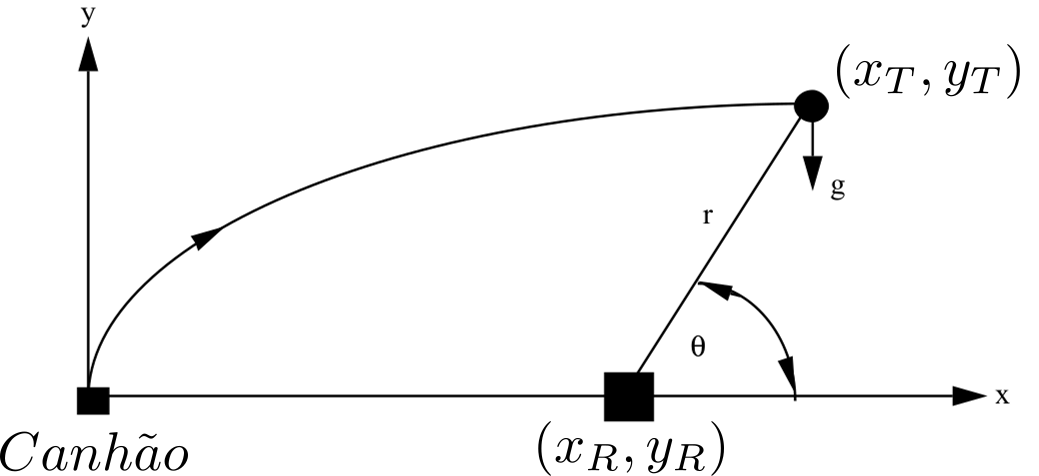

A física por trás desse problema diz respeito apenas a gravidade $\left(g\right)$ agindo sobre o projétil após o mesmo ter sido atirado. Pela figura, consegue-se encontrar uma relação matemática para expressar a distância entre o radar e a bala de canhão $\left(r\right)$ e o ângulo $\left(\theta \right)$, dados por:


$$\theta ={\mathrm{tan}}^{-1} \left(\frac{y_T -y_r }{x_T -x_r }\right)$$



$$r=\sqrt{\text{ }{\left(x_T -x_r \right)}^2 +{\left(y_T -y_r \right)}^2 }$$


A ideia por trás de se aplicar o filtro de Kalman Estendido no referido problema é fazer a estimação de velocidade e posição do projétil por meio de medidas obtidas pelo radar. Antes de aplicarmos propriamente o Filtro de Kalman, precisamos construir um modelo matemático que represente a posição e velocidade do projétil dada as variáveis $\theta \text{ }$e $r$. Sendo assim, tem-se que:


$$x_T =r\text{ }\mathrm{cos}\left(\theta \text{ }\right)+x_R$$



$$y_T =r\text{ }\mathrm{sen}\left(\theta \text{ }\right)+{y_R }$$


Sendo conhecida a posição do radar, as medidas obtidas por ele são ruidosas. Sendo assim, para se estimar a posição do corpo baseada apenas nas medidas do radar, a gente poderia proceder da seguinte forma:


$$\hat{x_T } =r^∗ \text{ }\cos \left(\theta^∗ \text{ }\right)+x_R$$



$$\hat{y_T } =r^∗ \text{ }\text{sen}\left(\theta^∗ \text{ }\right)+y_R$$


Para a determinação de velocidade, podemos utilizar a definição do cálculo, em que:


$$\hat{\dot{x_T } } =\frac{{\hat{x} }_{T_k } -{\hat{x} }_{T_{k-1} } }{T_s }$$



$$\hat{\dot{y_T } } =\frac{{\hat{y} }_{T_k } -{\hat{y} }_{T_{k-1} } }{T_s }$$


A grande problemática de se utilizar essa metodologia para determinação de posição e velocidade é que a gente utiliza os dados brutos obtidos pelo radar e reproduz a física dele. Não existe estimação no sentido estrito da palavra.

Para fazermos uso do Filtro de Kalman, a gente pode descrever a dinâmica do projeto em estados de espaço da forma:


$$\left\lbrack \begin{array}{c}
{\dot{x} }_T \\
{\ddot{x} }_T \\
{\dot{y} }_T \\
{\ddot{y} }_T 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0 & 1 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 1\\
0 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_T \\
{\dot{x} }_T \\
y_T \\
{\dot{y} }_T 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
-g
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
u_{s_1 } \\
0\\
u_{s_2 } 
\end{array}\right\rbrack$$


em que $u_s$ é um ruído adicionado ao termo de aceleração do como forma de proteção contra possíveis efeitos que não tenham sido considerados no Filtro de Kalman. Olhando a equação do sistema, tem-se que:


$$F=$$

$$\left\lbrack \begin{array}{c}
0 & 1 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 1\\
0 & 0 & 0 & 0
\end{array}\right\rbrack$$


Como a matriz fundamental é invariante ao tempo, tem-se que:


$$\Phi \left(t\right)=I+\mathrm{Ft}+\frac{F^2 t^2 }{2!}+\frac{F^3 t^3 }{3!}+\dots$$


Se você executar as multiplicação, encontrará que:


$$F^2 =\left\lbrack \begin{array}{c}
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0
\end{array}\right\rbrack$$


e portanto:


$$\Phi \left(t\right)=I+\text{Ft}=\left\lbrack \begin{array}{c}
1 & t & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & t\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$
 

A tempo discreto, nos instantes de amostragem $\left(T_s \right)$, tem-se que:


$$\Phi_k =\left\lbrack \begin{array}{c}
1 & T_s  & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & T_s \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


Dada a escolha cartesiana do vetor de estados, as medidas de $\theta \text{ }$e $r$ são funções não lineares dos elementos do vetor de estados. Mais precisamente, tem-se que:


$$\left\lbrack \begin{array}{c}
\Delta \theta {\text{ }}^∗ \\
\Delta r{\text{ }}^∗ 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{\partial }{\partial x_T }\theta \text{ } & \frac{\partial }{\partial {\dot{x} }_T }\theta \text{ } & \frac{\partial }{\partial y_T }\theta \text{ } & \frac{\partial }{\partial {\dot{y} }_T }\theta \text{ }\\
\frac{\partial }{\partial x_T }r & \frac{\partial }{\partial {\dot{x} }_T }r & \frac{\partial }{\partial y_T }r & \frac{\partial }{\partial {\dot{y} }_T }r
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\Delta x}_T \\
{\dot{\Delta x} }_T \\
{\Delta y}_T \\
{\dot{\Delta y} }_T 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
v_{\theta \text{ }} \\
v_r 
\end{array}\right\rbrack$$


em que $v_{\theta \text{ }}$e $v_r$ representam os ruidos de medida, respectivamente. Para a determinação da matriz $H$é importante que derivamos parcialmente as funções uma a uma, resultando em:


$$H=\left\lbrack \begin{array}{c}
\frac{-\left(y_T -y_R \right)}{r^2 } & 0 & \frac{\left(x_T -x_R \right)}{r^2 } & 0\\
\frac{\left(x_T -x_R \right)}{r} & 0 & \frac{\left(y_T -y_R \right)}{r} & 0
\end{array}\right\rbrack$$


A matriz $R$ é dada por:


$$R=E\left({\mathrm{vv}}^T \right)=E\left(\left\lbrack \begin{array}{c}
v_{\theta \text{ }} \\
v_r 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_{\theta }  & v_r 
\end{array}\right\rbrack \right)=E\left(\left\lbrack \begin{array}{c}
v_{\theta }^2  & 0\\
0 & v_r^2 
\end{array}\right\rbrack \right)=\left\lbrack \begin{array}{c}
{\sigma_{\theta } }^2  & 0\\
0 & {\sigma_r }^2 
\end{array}\right\rbrack$$


em que:

- $E\left(v_{\theta }^2 \right)=$${\sigma_{\theta } }^2$;

- $E\left(v_r^2 \right)=$${\sigma_r }^2$; e

-  as medidas são consideradas descorrelacionadas (ou seja, $v_{\theta }$$v_r =0$).

Para a determinação da matriz Q, tem-se que:


$$Q\left(t\right)=E\left({\text{ww}}^T \right)=E\left(\left\lbrack \begin{array}{c}
0\\
{u_s }_1 \\
0\\
u_{s_2 } 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0 & u_{s_1 }  & 0 & u_{s_2 } 
\end{array}\right\rbrack \right)=E\left(\left\lbrack \begin{array}{c}
0 & 0 & 0 & 0\\
0 & u_{s_1 }^2  & 0 & u_{s_1 } u_{s_2 } \\
0 & 0 & 0 & 0\\
0 & u_{s_1 } u_{s_2 }  & 0 & u_{s^2 } 
\end{array}\right\rbrack \right)=$$

$$\left\lbrack \begin{array}{c}
0 & 0 & 0 & 0\\
0 & \Phi_{s_1 }  & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & \Phi_{s_2 } 
\end{array}\right\rbrack$$


em que $\Phi_{s_1 }$ e $\Phi_{s_2 }$ é a densidade espectral do ruído branco assumido agindo nas duas acelerações do sistema, há o descorrelacionamento entre elas (por isso que foi considerado $\left.E\left(u_{s_1 } u_{s_2 } \right)=0\right)$ e no final das contas se considerou que $E\left(u_{s_1 }^2 \right)=E\left(u_{s_2 }^2 \right)=\Phi_s$. Tem-se que ser determinada essa matriz a tempo discreto, ela é dada por:


$$Q_k =\int_0^{T_s } \Phi \text{ }\left(\tau \text{ }\right)Q\left(t\right)\Phi {\text{ }}^T \left(\tau \text{ }\right)d\tau \text{ }$$


Então, tem-se que:


$$Q_k =\Phi_s \int_0^{T_s } \left\lbrack \begin{array}{c}
1 & \tau  & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & \tau \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1 & 0 & 0 & 0\\
\tau  & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & \tau  & 1
\end{array}\right\rbrack d\tau \text{ }$$


Que após algumas multiplicações e integração resulta em:


$$Q_k =\left\lbrack \begin{array}{c}
\frac{T_s^3 }{3} & \frac{T_s^2 }{2} & 0 & 0\\
\frac{T_s^2 }{2} & T_s  & 0 & 0\\
0 & 0 & \frac{T_s^3 }{3} & \frac{T_s^2 }{2}\\
0 & 0 & \frac{T_s^2 }{2} & T_s 
\end{array}\right\rbrack$$


Sendo assim, tem-se todas as equações necessárias para a realização da filtragem de Kalman Estandida.

Inicialmente, irei limpar todas as variáveis e janelas que possa existir.

clear; close all; clc;

Em seguida, irei fazer as setagens de alguns parâmetros do meu sistema, como:

- Tempo de amostragem;

- Tempo total de simulação; e

- Passo de integração.

% Parâmetros para a simulação.
Ts   = 1;
Tsim = 130;
h    = 0.001;

Setagem da condição inicial de lançamento do projétil:

% Setagem inicial (ângulo e velocidade de disparo).
ang0 = 45;
v0   = 3000;
g    = 32.2;

Resultado em um vetor de estados inicial dado por:

% Condições iniciais.
x0  = 0;
vx0 = v0*cos(ang0*pi/180);
y0  = 0;
vy0 = v0*sin(ang0*pi/180);

% Vetor na condição inicial.
X{1} = [x0; vx0; y0; vy0];

Para a rodagem do sistema na simulação em Runge-Kutta de 2º ordem, temos que criar o sistema recursivo, dado por:

% Matriz A e B do sistema.
A = [0 1 0 0;
     0 0 0 0;
     0 0 0 1;
     0 0 0 0];
B = [ 0; 0; 0; -g];

j = 0;
for i = 1:((Tsim/h) + 1)
    t(i) = (i-1)*h;
    
    % Como no Runge-Kutta de 2º ordem a gente precisa realiza o
    % cálculo de:
    %
    % * p1   = f(X{i}, t(i) + h)
    %
    % * p2   = f(X{i}, t(i));
    %
    % Como o Live-Editor não possibilita a utilização de função, 
    % A gente simplesmente replicou a mesma. Este caso fica fácil,
    % pois a dinâmica do sistema não depende da variável 't').
    p1 = A*X{i} + B;
    p2 = A*X{i} + B;
    
    X{i+1} = X{i} + (1/2)*h*(p1 + p2);
    xt(i)  = X{i}(1,1);
    yt(i)  = X{i}(3,1);
    
    % Apenas para fins de plotagem.
    if (mod(t(i), Ts) == 0)
        % Atualizo o contador.
        j = j + 1;
        
        x_sample(j)  = X{i}(1,1);
        vx_sample(j) = X{i}(2,1);
        y_sample(j)  = X{i}(3,1);
        vy_sample(j) = X{i}(4,1);
    end
end

Vamos agora plotar o resultado da dinâmica do sistema apenas para visualizar o resultado e ver se ele está correto.

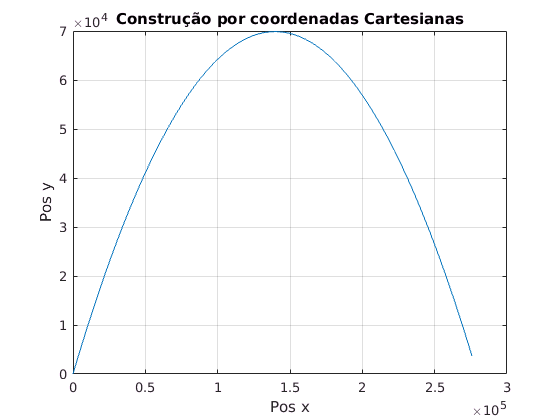

% Plota o resultado -- apenas para conferência.
plot(xt, yt);
xlabel('Pos x');
ylabel('Pos y');
grid;
title('Construção por coordenadas Cartesianas');

Vamos agora fazer as tratativas como determinação das variáveis em estudo, sejam elas a distância entre o radar e abala de canhão $\left(r\right)$ e o ângulo $\left(\theta \right)$, pois são as variáveis as quais o radar efetivamente coleta.

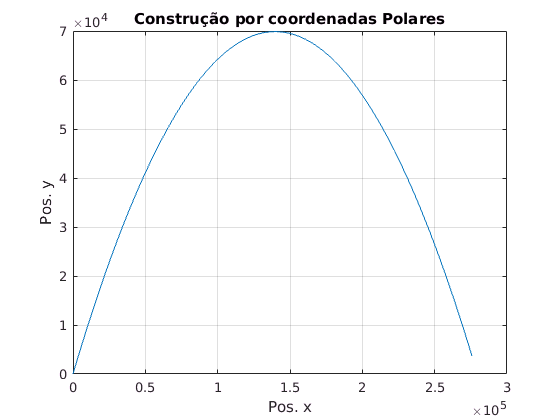

% Posição do radar.
xr = 100000;            
yr = 0;

for i = 1:max(size(xt))
    % Cálculo do 'r'.
    r(i)     = sqrt((yt(i) - yr)^2 + (xt(i) - xr)^2);
    
    % Cálculo do 'theta'.
    theta(i) = atan2((yt(i) - yr), (xt(i) - xr));
    % Uma vez que a função 'atan2' não normaliza o ângulo no 
    % intervalor [0, 2*pi] e sim em [-2*pi, 2*pi], a gente faz essa adaptação.
    if (theta(i) < 0)
        theta(i) = 2*pi + theta(i);
    end
    
    % Posição final, por meio de coordenadas polares.
    px(i)    = r(i)*cos(theta(i)) + xr;
    py(i)    = r(i)*sin(theta(i)) + yr;
end

% Plota o resultado -- apenas para conferência.
figure;
plot(px, py);
xlabel('Pos. x');
ylabel('Pos. y');
grid;
title('Construção por coordenadas Polares');

Nas medidas obtidas pelo radar (distância entre o radar e abala de canhão $\left(r\right)$ e o ângulo $\left(\theta \right)$), vamos fazer a inserção de ruído nos instantes em que o radar faz a amostragem do sinal:

% Inserção do ruído nas medidas de ângulo e de distância
sigma_r     = 100;
sigma_theta = 0.01;
media_r     = 0;
media_theta = 0;

% Quantidade de amostras -- n.
QuantSamples = ((Tsim/Ts) + 1);       

ruido_r     = (    media_r + sigma_r*rand(QuantSamples, 1))';
ruido_theta = (media_theta + sigma_theta*rand(QuantSamples, 1))';

% Nos instantes de amostragem eu faço a inserção do ruído na medida real.
j = 0;      % inicializo o contador.
for i = 1:max(size(xt))
    if (mod(t(i), Ts) == 0)
        % Atualizo o contador.
        j = j + 1;
        
        % Insiro um ruído.
        r_ruidoso(j)     =     r(i) + ruido_r(j);
        theta_ruidoso(j) = theta(i) + ruido_theta(j);
        
        % Reconstruo o sinal em cima das medidas ruidosas.
        px_ruidoso(j) = r_ruidoso(j)*cos(theta_ruidoso(j)) + xr;
        py_ruidoso(j) = r_ruidoso(j)*sin(theta_ruidoso(j)) + yr;    
    end
end

Ploto o resultado do sinal com ruído (meio que representa a vida real):

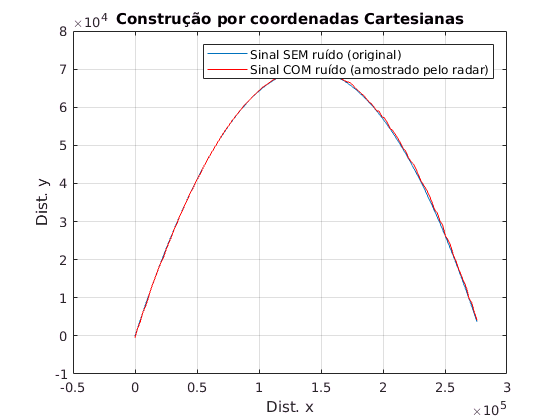

% Plota resultado -- apenas para conferência.
figure;
plot(px, py, px_ruidoso, py_ruidoso, 'r');
xlabel('Dist. x');
ylabel('Dist. y');
grid;
legend('Sinal SEM ruído (original)', 'Sinal COM ruído (amostrado pelo radar)');
title('Construção por coordenadas Cartesianas');

Tomando como base os resultados obtidos obtidos via amostragem do radar e do modelo de simulação (já exposto lá em cima), a gente agora construirá as matrizes que serão utilizadas no Filtro de Kalman Estendido.

% Determinação de algumas matrizes do sistema para Kalman Filter.
% ===============================================================

% Matriz 'PHI' (do tipo 'I + F*t')
F    = [0  1  0  0;
        0  0  0  0;
        0  0  0  1;
        0  0  0  0];
% Para o instante de amostragem escolhido, tem-se que:
I    = eye(4);
PHI  = I + (F * Ts);

% Matriz 'R' -- Essa matriz aqui não muda durante a simulação. 
R    = [sigma_theta^2     0;
              0         sigma_r^2];
          
% Matriz Q{k} -- Aparentemente a equação do livro está errada.
% Esta que segue de algumas deduções (considere ela correta).
% Essa matriz também não muda.
Q = [(Ts^3)/3  (Ts^2)/2       0        0;
     (Ts^2)/2      Ts         0        0;
         0         0      (Ts^3)/3  (Ts^2)/2;
         0         0      (Ts^2)/2     Ts];
% Inicialmente não vamos considerar erro no modelo, para uma primeira análise.
PHI_s = 0;
Q     = PHI_s*Q;

% Inicialização do problema (estimativas iniciais para o vetor de estados).
delta    = [ 1000; -100; -1000; 100];
x_hat{1} = X{1} + delta;
        
% Inicialização da matriz de covariância.
P0 = [delta(1)^2     0          0           0;
          0      delta(2)^2     0           0;
          0          0       delta(3)^2     0;
          0          0          0       delta(4)^2];

Vamos agora rodar efetivamente o Filtro de Kalman:

cont = 0;     % Contador (utilizado apenas quando foram os instantes de amostragem).

for k = 1:((Tsim/h) + 1)
    
    % Base de tempo.
    tempo(k) = (k-1)*h;
    
    % ===================================================================
    % Nos INSTANTES DE AMOSTRAGEM, temos de fazer o nosso ajuste baseado:
    % 
    % 1. Medidas obtidas pelo radar (com ruído); e
    % 2. Pelo modelo matemático.
    % ===================================================================
    if (mod(tempo(k), Ts) == 0)
        
        % Atualizo o contador.
        cont = cont + 1;
        
        % Qual a melhor estimativa do vetor de estados até o presente
        % momento? 
        % Isso mesmo: 'x_hat'. A gente, no futuro, vai melhorar essa melhor estimativa.so
        x_good{cont} = x_hat{k};
        
        % Apenas quebro as variáveis para o plot em seguida.
        x_de_t_hat(cont) = x_good{cont}(1,1);
        y_de_t_hat(cont) = x_good{cont}(3,1);
        
        % Eu consigo reconstruir o 'theta' e o 'r' por meio da melhor
        % estimativa e da física do problema, por meio de:
        r_good(cont)     = sqrt((y_de_t_hat(cont) - yr)^2 + (x_de_t_hat(cont) - xr)^2);
        
        % Cálculo em cima do 'theta', uma vez que a função 'atan2' não
        % normaliza o angulo no intervalor [0, 2*pi] e sim em [-2*pi, 2*pi]
        theta_good(cont) = atan2((y_de_t_hat(cont) - yr), (x_de_t_hat(cont) - xr));
        if (theta_good(cont) < 0)
           theta_good(cont) = 2*pi + theta_good(cont);
        end
       
        % O meu problema de exige uma matriz 'H', dada por:
        % H   = matrizH(x_de_t_hat(cont), y_de_t_hat(cont), xr, yr);
        rh     = sqrt((x_de_t_hat(cont) - xr)^2 + (y_de_t_hat(cont) - yr)^2);
        H(1,1) = -(y_de_t_hat(cont) - yr)/(rh*rh);
        H(1,2) = 0;
        H(1,3) = (x_de_t_hat(cont) - xr)/(rh*rh);
        H(1,4) = 0;
        H(2,1) = (x_de_t_hat(cont) - xr)/rh;
        H(2,2) = 0;
        H(2,3) = (y_de_t_hat(cont) - yr)/rh;
        H(2,4) = 0;
      
        % Equações de Riccati
        if( cont == 1 )
            M{cont} = PHI * P0 * (PHI') + Q;
            K{cont} = M{cont} * (H') * inv((H * M{cont} * (H') + R));
            P{cont} = (I - K{cont} * H) * M{cont};
        else
            M{cont} = PHI * P{cont-1} * (PHI') + Q;
            K{cont} = M{cont} * (H') * inv((H * M{cont} * (H') + R));
            P{cont} = (I - K{cont} * H) * M{cont};
        end
        
        % Vamos melhorar a estimativa.
        diferenca{cont}    = [(theta_ruidoso(cont) - theta_good(cont));
                              (r_ruidoso(cont)     - r_good(cont))];

        % Esta parte é muito importante, pois a gente utilizará:
        %
        % 1. A melhor estimativa disponível até então (x_good);
        % 2. O cálculo dado o modelo matemático disponível
        x_hat{k}     = x_good{cont} + K{cont} * diferenca{cont};
        xh_sample(cont)  = x_hat{k}(1,1);
        vxh_sample(cont) = x_hat{k}(2,1);
        yh_sample(cont)  = x_hat{k}(3,1);
        vyh_sample(cont) = x_hat{k}(4,1);
    end
    
    % Se não for o instante de amostragem, continuem a utilizar a
    % integração, utilizando as estimativas do sinal.
    %
    % Como no Runge-Kutta de 2º ordem a gente precisa realiza o
    % cálculo de:
    %
    % * p1   = f(X{i}, t(i) + h)
    %
    % * p2   = f(X{i}, t(i));
    %
    % Como o Live-Editor não possibilita a utilização de função, 
    % A gente simplesmente replicou a mesma. Este caso fica fácil,
    % pois a dinâmica do sistema não depende da variável 't').
    p1 = A*x_hat{k} + B;
    p2 = A*x_hat{k} + B;
    x_hat{k+1} = x_hat{k} + (1/2)*h*(p1 + p2);
end

Agora eu pego as variáveis melhor estimadas do vetor de estado e faço o plot das mesmas para saber se funcionou mais ou menos bem o Filtro de Kalman.

% Pego as variáveis do sistema.
for i = 1:max(size(x_hat))
      xh(i)  = x_hat{i}(1,1);
      vxh(i) = x_hat{i}(2,1);
      yh(i)  = x_hat{i}(3,1);      
      vyh(i) = x_hat{i}(4,1);
end

% De forma equivalente, os valores das covariâncias do sistema.
for k = 1:max(size(P))
      p11(k) = P{k}(1,1);
      p22(k) = P{k}(2,2);
      p33(k) = P{k}(3,3);
      p44(k) = P{k}(4,4);
end

Faço o plot das variáveis em termos de valores reais e também em termos dos valores estimados.

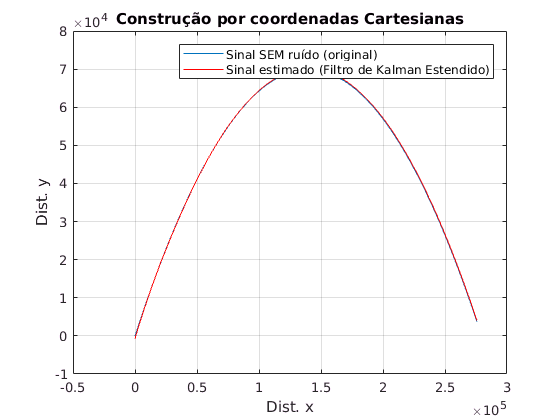

figure;
plot(px, py, xh, yh, 'r');
xlabel('Dist. x');
ylabel('Dist. y');
grid;
legend('Sinal SEM ruído (original)', 'Sinal estimado (Filtro de Kalman Estendido)');
title('Construção por coordenadas Cartesianas');

Pela figura acima, não dá para se ter um pleno entendimento do funcionamento do Filtro de Kalman Estendido. Para melhor entender o resultado obtido, vamos fazer um plot paralelo das variáveis.

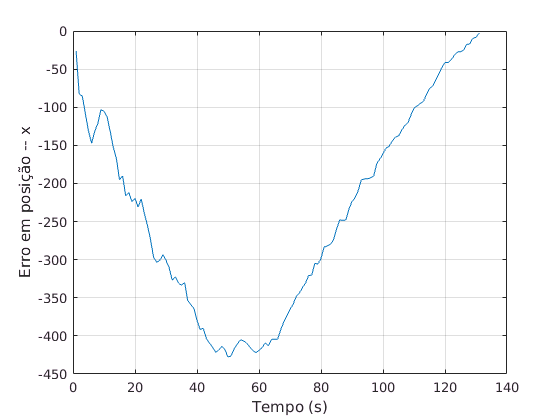

% Pela figura acima, não dá para se ter um pleno entendimento do funcionamento do Filtro de Kalman Estendido. Para melhor entender o resultado obtido, vamos fazer um plot paralelo das variáveis.
% Erro em posição 'x'
figure;
erro_x = x_sample - xh_sample;
plot(erro_x);
grid;
xlabel('Tempo (s)');
ylabel('Erro em posição -- x');

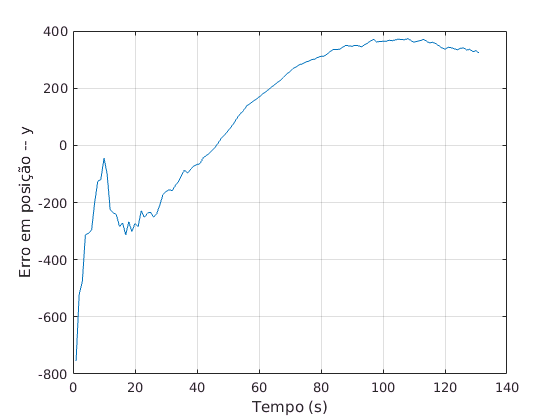


% Erro em posição 'y'
figure;
erro_y = y_sample - yh_sample;
plot(erro_y);
grid;
xlabel('Tempo (s)');
ylabel('Erro em posição -- y');

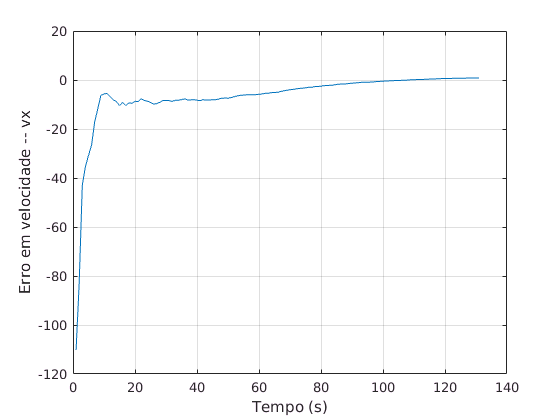


% Erro em velocidade 'vx'
figure;
erro_vx = vx_sample - vxh_sample;
plot(erro_vx);
grid;
xlabel('Tempo (s)');
ylabel('Erro em velocidade -- vx');

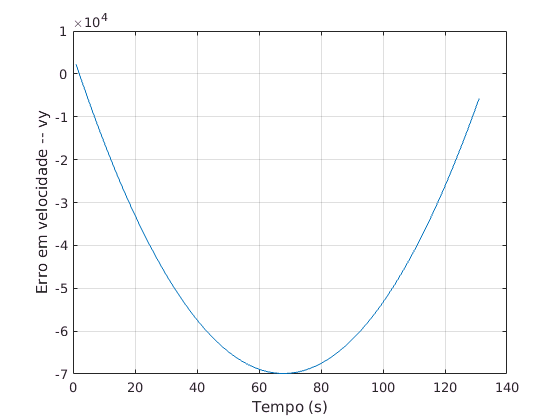


% Erro em velocidade 'vy'
figure;
erro_vy = vy_sample - vyh_sample;
plot(erro_vy);
grid;
xlabel('Tempo (s)');
ylabel('Erro em velocidade -- vy');